# Control Script

## Clear Workspace

close all; clearvars; clc;

## Initialize Variables

numChannels = 4;            % Number of electrodes in the system
SkipN = 0;                  % Number of electrodes to skip
N = 1024;                   % Number of samples taken
sampleRate = 125e3;         % Sets the rate that the NI-Boards sample at
outputRate = 1e6;           % Sets the rate that the NI-Board output at
bufferForPreLoad = 500e3;   % sets the length of buffer for preloading
pkpV = 0.2;                  % pk-pk voltage per frequency
frq = [10e3 30e3 50e3];
phase = [0 pi];

## Add Digital Mux Select

MuxDigiOut = daq("ni");
MuxBrd1 = addoutput(MuxDigiOut, "Dev1", "port1/line0:4","Digital"); % adds the digital mux data lines for board 1

MuxBrd2 = addoutput(MuxDigiOut, "Dev2", "port1/line0:4", "Digital"); % adds the digital mux data lines for board 2

## Add Digital Switch Select

SwitchSelect = daq("ni");
SWBrd1 = addoutput(SwitchSelect, "Dev1", "port2/line0:3","Digital"); % adds the digital switch data lines for board 1

%SWBrd2 = addoutput(SwitchSelect, "Dev2", "port2/line0:7", "Digital"); % adds the digital switch data lines for board 2

## Add Analog Output

dAOut = daq("ni"); % Initialize connection to the NI-Board for analog output
AnalogCH1 = addoutput(dAOut,"Dev1","ao0","Voltage"); % adds the analog output for board 1
AnalogCH2 = addoutput(dAOut,"Dev2","ao0","Voltage"); % adds the analog output for board 2

%uncomment if using multiple boards for DAQ
% Use |addtrigger| to add a digital start trigger from (|'RTSI0/PFI3'|
% (source) to |'RTSI0/Dev4'| (destination)
addtrigger(dAOut,"Digital","StartTrigger","Dev1/RTSI0","Dev2/RTSI0");

% Use |addclock| to share a scan clock using the |RTSI1| terminal
% connection.
addclock(dAOut, "ScanClock", "Dev1/RTSI1","Dev2/RTSI1");

dAOut.Rate = outputRate; % sets the output sampling rate Hz

outputSignal = [createSine(pkpV/2, frq, phase(1), outputRate, "bipolar", bufferForPreLoad) createSine(pkpV/2, frq, phase(2), outputRate, "bipolar", bufferForPreLoad)]; % calls function to generate wave vector

% Uncomment to see signal being injected
% t = (0:(N-1)) / sampleRate;
% figure;
% plot(t, outputSignal(1:N))
% title('Generated Output')
% source = outputSignal(1:N);

preload(dAOut,outputSignal); % loads wave vector into NI-Board

## Add ADC Inputs

dDAQ = daq("ni");
dDAQ.Rate = 125e3; %2^17

ch1 = addinput(dDAQ,"Dev1","ai0","Voltage");
ch1.TerminalConfig = "SingleEnded";
ch1.Range = [-10 10];
ch2 = addinput(dDAQ,"Dev1","ai1","Voltage");
ch2.TerminalConfig = "SingleEnded";
ch2.Range = [-10 10];
ch3 = addinput(dDAQ,"Dev1","ai2","Voltage");
ch3.TerminalConfig = "SingleEnded";
ch3.Range = [-10 10];
ch4 = addinput(dDAQ,"Dev1","ai3","Voltage");
ch4.TerminalConfig = "SingleEnded";
ch4.Range = [-10 10];
%{
ch5 = addinput(dDAQ,"Dev1","ai4","Voltage");
ch5.TerminalConfig = "SingleEnded";
ch5.Range = [-1 1];
ch6 = addinput(dDAQ,"Dev1","ai5","Voltage");
ch6.TerminalConfig = "SingleEnded";
ch6.Range = [-1 1];
ch7 = addinput(dDAQ,"Dev1","ai6","Voltage");
ch7.TerminalConfig = "SingleEnded";
ch7.Range = [-1 1];
ch8 = addinput(dDAQ,"Dev1","ai7","Voltage");
ch8.TerminalConfig = "SingleEnded";
ch8.Range = [-1 1];
ch9 = addinput(dDAQ,"Dev2","ai0","Voltage");
ch9.TerminalConfig = "SingleEnded";
ch9.Range = [-5 5];
ch10 = addinput(dDAQ,"Dev2","ai1","Voltage");
ch10.TerminalConfig = "SingleEnded";
ch10.Range = [-1 1];
ch11 = addinput(dDAQ,"Dev2","ai2","Voltage");
ch11.TerminalConfig = "SingleEnded";
ch11.Range = [-1 1];
ch12 = addinput(dDAQ,"Dev2","ai3","Voltage");
ch12.TerminalConfig = "SingleEnded";
ch12.Range = [-1 1];
ch13 = addinput(dDAQ,"Dev2","ai4","Voltage");
ch13.TerminalConfig = "SingleEnded";
ch13.Range = [-1 1];
ch14 = addinput(dDAQ,"Dev2","ai5","Voltage");
ch14.TerminalConfig = "SingleEnded";
ch14.Range = [-1 1];
ch15 = addinput(dDAQ,"Dev2","ai6","Voltage");
ch15.TerminalConfig = "SingleEnded";
ch15.Range = [-1 1];
ch16 = addinput(dDAQ,"Dev2","ai7 ","Voltage");
ch16.TerminalConfig = "SingleEnded";
ch16.Range = [-1 1];
%}

### Add Triggers and Scan Clock for Synchronization to ADC Inputs

%{
uncomment if using multiple boards for DAQ
% Use |addtrigger| to add a digital start trigger from (|'RTSI2/PFI3'|
% (source) to |'RTSI0/Dev4'| (destination)
addtrigger(dDAQ,"Digital","StartTrigger","Dev1/RTSI2","Dev2/RTSI2");

% Use |addclock| to share a scan clock using the |RTSI3| terminal
% connection.
addclock(dDAQ, "ScanClock", "Dev1/RTSI3","Dev2/RTSI3");
%}

## Collect Data Vector

### Set State

### Main Loop

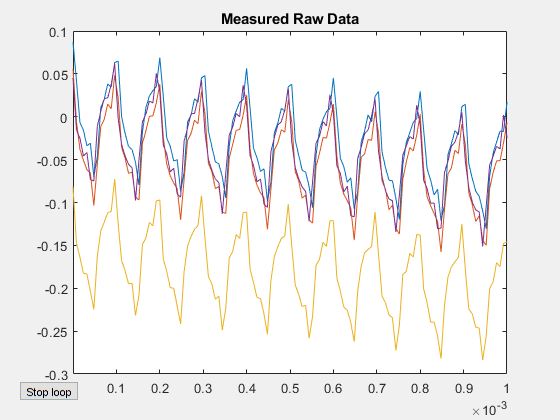

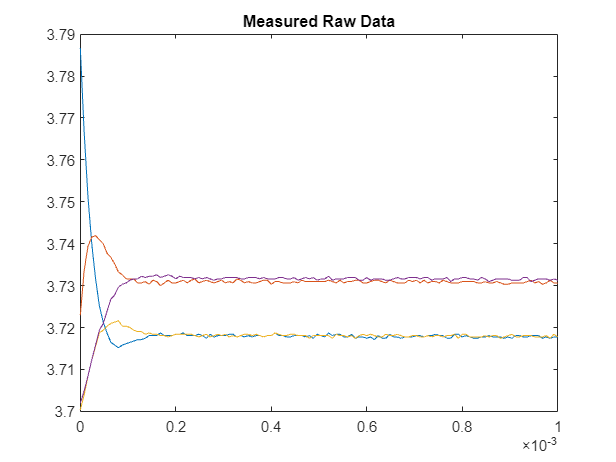

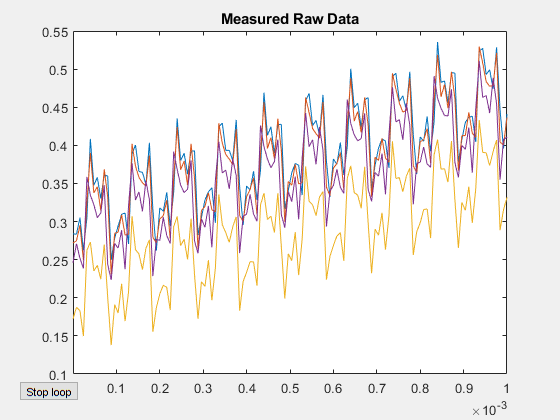

Loop stopped by user


figure
ButtonHandle = uicontrol('Style', 'PushButton', ...
                         'String', 'Stop loop', ...
                         'Callback', 'delete(gcbf)');
start(dAOut,"repeatoutput"); % starts wave output from the NI-Board
figure(2)
loopNumChannels = numChannels-1;
while true
    for i = 0:1:loopNumChannels
        muxSet = setMux(MuxDigiOut, i, SkipN, loopNumChannels);
        electrodeSet = setElectrode(SwitchSelect, i, SkipN, numChannels);
        [signal,time] = read(dDAQ, N, "OutputFormat", "Matrix");
        clf(2)
        plot(time,signal)
        title('Measured Raw Data')
        xlim([0 1e-3])
        pause(0.5)
        

    end
    if ~ishandle(ButtonHandle)
        disp('Loop stopped by user');
        break;
    end
end

## Stop Outpuss

stop(dAOut);
stop(MuxDigiOut);
stop(SwitchSelect);

## Sine Function

function sine = createSine(A, frq, phase, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    periods = 1/eval(gcd(sym(frq))); % calculates the length of the period for a periodic
    t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period
    y = sum(A*sin(2.*pi.*frq.*t+phase),2); % calculates the signal along the time vector
    
    if type == "unipolar"
        y = y + max(y); % if the signal is unipolar add the max amplitude to make it all positive
    end
    
    numCycles = ceil(bufferForPreLoad/length(y)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end

## Mux Function

function muxSet = setMux(device, currentInjection, skipNum, numChannels)
    muxSet = [1, flip(str2double(num2cell(dec2bin(mod(currentInjection, numChannels), 4)))), 1, flip(str2double(num2cell(dec2bin(mod(currentInjection + skipNum+1, numChannels), 4))))];
    write(device, muxSet);
end

## Electrode Select Function

function electrodeSet = setElectrode(device, currentInjection, skipNum, numChannels)
    electrodeSet = [~flip(str2double(num2cell(dec2bin(bitor(bitshift(1,mod(currentInjection, numChannels)), bitshift(1,mod(currentInjection+skipNum+1, numChannels))), numChannels)))) ];
    write(device, electrodeSet);
end

## Frequency Demodulation

function ampPhase = multiFreqDemod(signal, frq, sampleLen, sampleFreq)
    k = 0:sampleLen-1; % vector of n points
    tk = (k/sampleFreq)'; % xAxis
    
    w = 2*pi*frq;     % frequency converted to anglar frequency (rad/s)
    
    % matrix containing the desired frequency component of the system
    Etot = [sin(w.*tk), cos(w.*tk)];
    
    for ii = 2:3:(length(frq)^2)
        Etot = [Etot(:,1:ii) ones(1, length(tk))', Etot(:,ii+1:end)];
    end
    % inverse of E * s^t (pinv)
    % phi1 = E(1)\signal; % gives alpha, beta and offset
    % phi2 = E(2)\signal;
    % phi3 = E(3)\signal;
    %phi_tot = pinv(Etot)*signal;
    phi_tot = lsqminnorm(Etot, signal); %(:,1); % compute ampliude, phase and dc offset
    
    ampPhase = reshape(phi_tot, length(frq), 3); % rearragnge to useful order
    ampPhase = ampPhase(1:2,length(frq)); % cut out dc as it is not needed
end